# Projeto do dia 16/10/2020

João Guilherme Martins Jatobá

18.01790-8

ECM303 - Sistemas de Controle

**Boas práticas**

clear all;
clc;
close all;



**Definindo o sistema dinâmico**

N = 1;
D = [1 1]

D =      1     1



Gp = tf(N,D)

Gp =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



**Visualização**

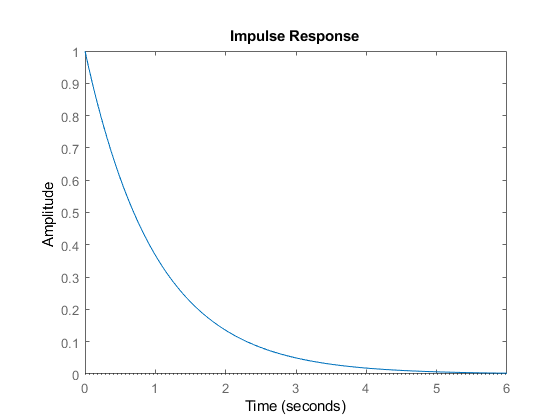

figure()
impulse(Gp)

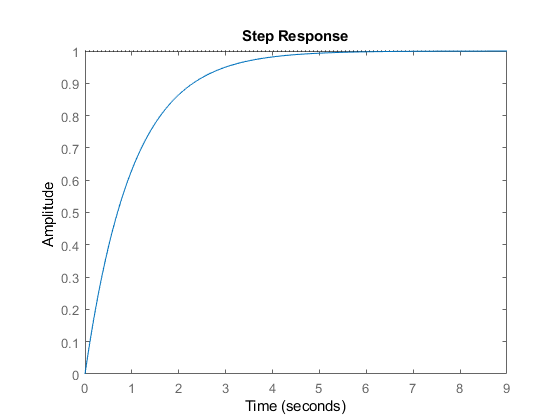


figure()
step(Gp)

**Sistema em Z**

T = 0.1;            %Taxa de amostragem
Nd = 1 - exp(-T);   %Numerador digital
Dd = [1 -exp(-T)];   % Denominador digital

Gpz = tf(Nd, Dd, T)     %funcao de transf discreta

Gpz =
 
   0.09516
  ----------
  z - 0.9048
 
Sample time: 0.1 seconds
Discrete-time transfer function.



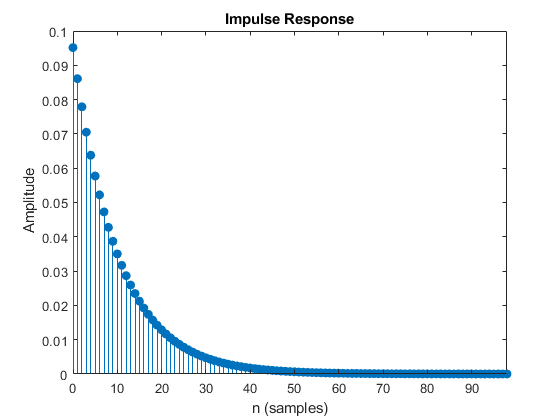


impz(Nd,Dd)

**Equação de Diferenças**


$$\frac{Y(z)}{U(z)} = \frac{a}{z-b} = \frac{az^{-1}}{1-bz^{-1}}$$


$y(n)  =au(n-1) + by(n-1)$(sera transformada em software)

**Trabalho**

% u(t) - acelerometro - entrada do sistema
% filtros passa baixas discreto de primeira ordem

%%% Gfiltros(s) = wc/(s+wc)

% Estimar wc

% Sugestao - FFT(u(T)) - descobrir a freq maxima de u(t) --> wc > fmax

% wc --> Gfiltro(s)
% Sugestao: usar o lsim para estimar o comportamento do filtro
%         : usar o comendo Bode para entender o filtro

% T - taxa de amostragem -- T = XXX.XXX segundos __> usar o diff para
% estimar a taxa de amsostragem
% Determinar Gfiltro(z)

% Determino a equacao de diferencas


**Solução**

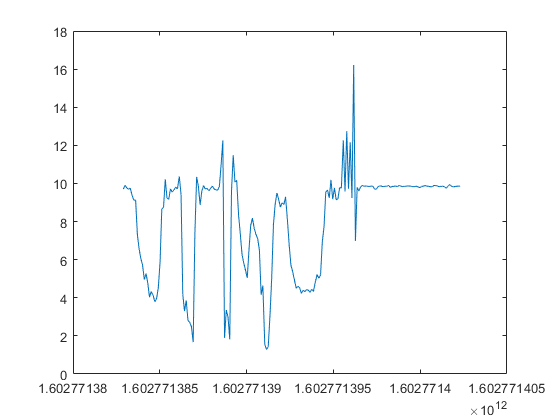

% Le os dados e atribui a variavel aux
aux = jsondecode(fileread('accelerometer_data.json'));

% Variavel tempo
tempo = vertcat(aux.timestamp);



% Empilha os dados para ter vetor
plot(tempo,vertcat(aux.z));


% Taxa de amostragem
T = mean(diff(tempo));

**Análise espectral**

% Vetor com variavel x
Ac_x = vertcat(aux.x);

% Transformada rapida de Fourier da variavel x
Ac_x_W = fftshift(fft(Ac_x))

Ac_x_W = 	1.0e+02 *

  -0.0203 + 0.0000i
  -0.0136 + 0.0432i
   0.0018 - 0.0032i
   0.0663 + 0.0111i
  -0.0266 - 0.0359i
  -0.0211 - 0.0398i
  -0.0068 + 0.0459i
  -0.0054 - 0.0186i
  -0.0063 - 0.0140i
  -0.0109 + 0.0338i


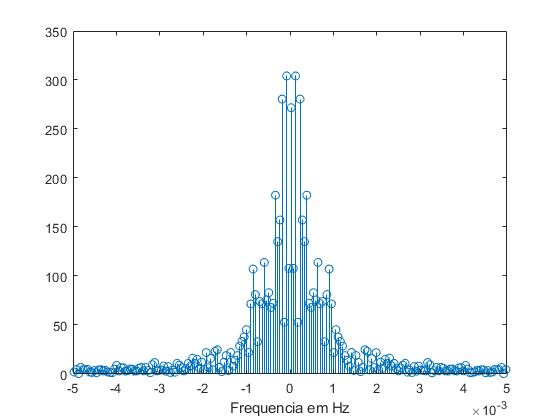


fs = 1/T; %freq de amostragem

M = length(Ac_x);   % numero de pontos

freq = linspace(-fs/2,fs/2,M); % frequencia do espectro
stem(freq,abs(Ac_x_W))
xlabel('Frequencia em Hz')

**Potência x Banda**

Pot_total = sum(abs(Ac_x_W).^2)

Pot_total = 7.6157e+05


Espectro_Unilateral = Ac_x_W(M/2+1:end)

Espectro_Unilateral = 	1.0e+02 *

  -2.7171 + 0.0000i
   0.9429 - 0.5220i
  -2.7395 + 1.3219i
   0.0031 + 0.5275i
  -0.1477 + 2.8013i
   1.5622 - 0.1722i
   0.9743 + 0.9355i
   0.7478 - 1.6641i
  -0.6981 + 0.1803i
   0.4815 + 0.4787i


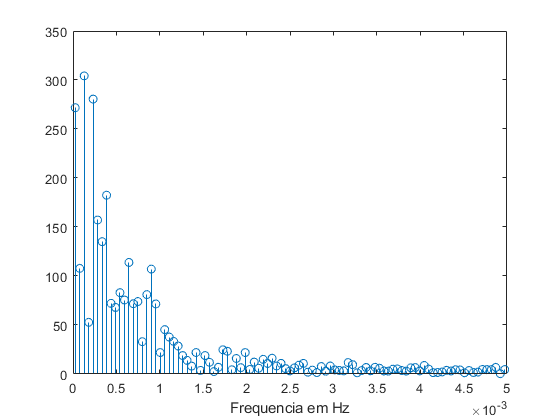


figure()
stem(freq(M/2+1:end),abs(Espectro_Unilateral))
xlabel('Frequencia em Hz')

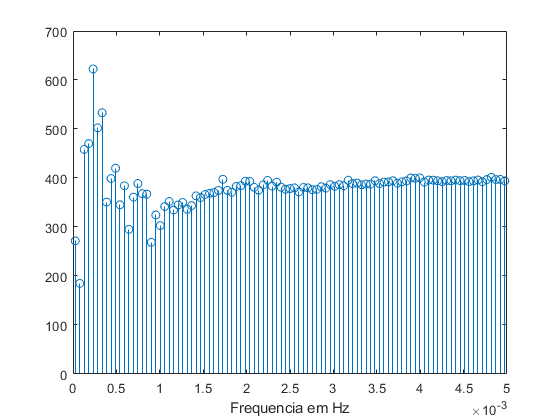


figure()
stem(freq(M/2+1:end),cumsum(abs(Espectro_Unilateral).^2))
xlabel('Frequencia em Hz')

**Conclusão**

wc = 2*pi*2;    % freq de corte de filtro
